# **SVD applied to an image**

*Eren Alagoz, adapted from V. Matray's training sessions*

clear all
close all
clc

## Decomposition by SVD

### Load original image

UCimage = imread('callas.jpg');
UCimage = im2double(UCimage(:,:,1));
figure
subplot(1,2,1)
colormap(gray); imagesc(UCimage(:,:));axis equal;axis tight; axis off;
title ('Maria Callas')

### Get dimensions of the image

n_T = size(UCimage, 1);
n_M = size(UCimage, 2);
M = UCimage;

### SVD on the image

[U,S,V] = svd(M);

### Order for reconstruction ?

order = 100;

### Initialize the reconstruction 

M_POD = zeros(n_M,n_T)';

### Reconstruction :

for o = 1:order
    M_POD = M_POD + U(:,o) * S(o,o) * V(:,o)';
end

### Optional challenge: build M_POD using a single Matlab line 

### plot

subplot(1,2,2)
colormap(gray); imagesc(M_POD(:,:));axis equal;axis tight; axis off;
title("Approximation with "+order+" modes")

## Calculation of the reconstruction error

### Plot the reconstruction error as a function of the number of modes used. The reconstruction error considered here will be calculated with the norm of your choice (you can use the "norm" function of Matlab it's the fastest/ easiest way ;) ). 

%gain
gain = (n_T * n_M) / (order * (n_T + n_M + 1));
fprintf('Storage gain with %d modes: %.2f\n', order, gain);

Storage gain with 100 modes: 3.00


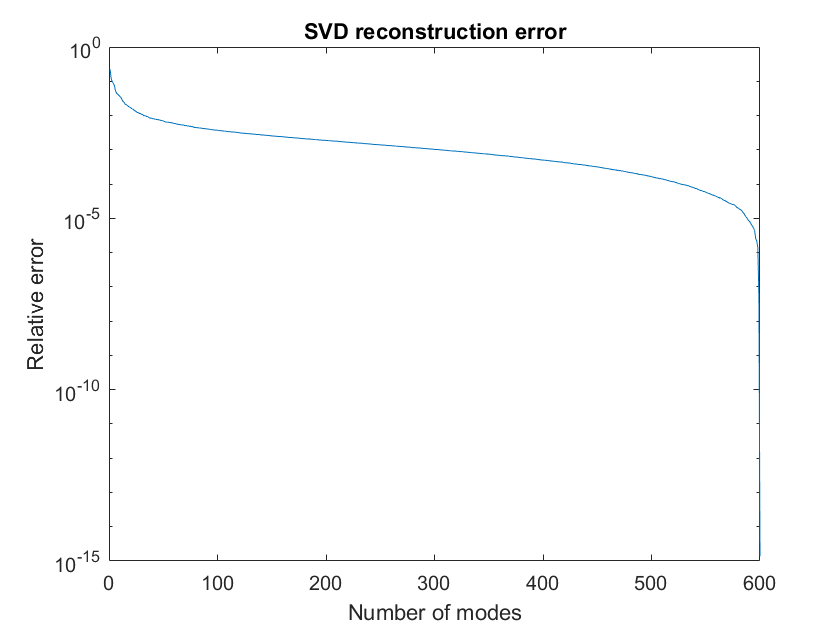

%% Reconstruction error vs number of modes
max_modes = min(n_T, n_M);
M_POD = zeros(n_M, n_T)';
M_err = zeros(max_modes, 1);

for o = 1:max_modes
    M_POD = M_POD + S(o,o) * U(:,o) * V(:,o)';
    M_err(o) = norm(M - M_POD) / norm(M);
end

figure
semilogy(1:max_modes, M_err)
xlabel('Number of modes')
ylabel('Relative error')
title('SVD reconstruction error')

%% Deduce optimal number of modes
tol = 0.01;  % 1% error threshold
N_opt = find(M_err < tol, 1);
gain_opt = (n_T * n_M) / (N_opt * (n_T + n_M + 1));
fprintf('Optimal modes (error < %.0f%%): %d\n', tol*100, N_opt);

Optimal modes (error < 1%): 32


fprintf('Effective storage gain: %.2f\n', gain_opt);

Effective storage gain: 9.37


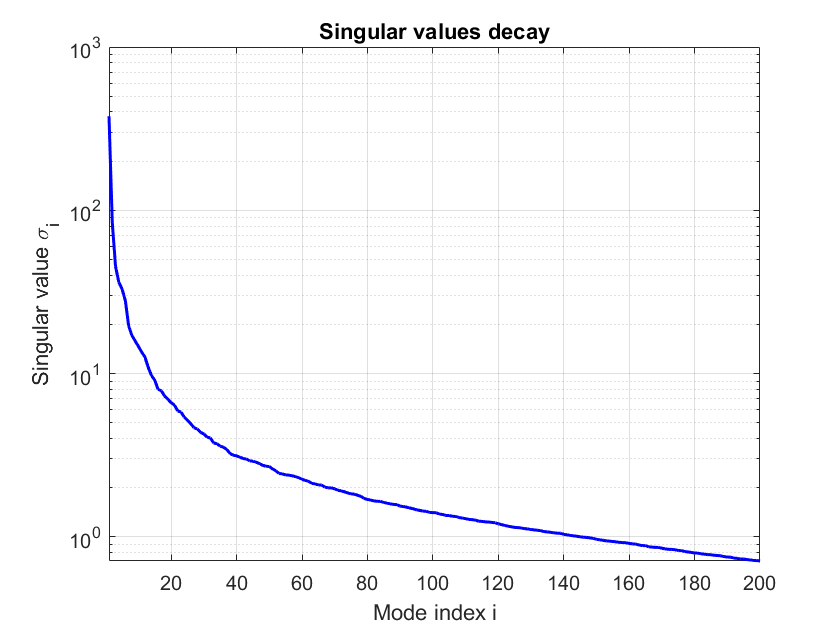

figure
semilogy(diag(S), 'b-', 'LineWidth', 1.5)
xlabel('Mode index i')
ylabel('Singular value \sigma_i')
title('Singular values decay')
grid on
xlim([1 200])
saveas(gcf, 'svd_singular_values.png')

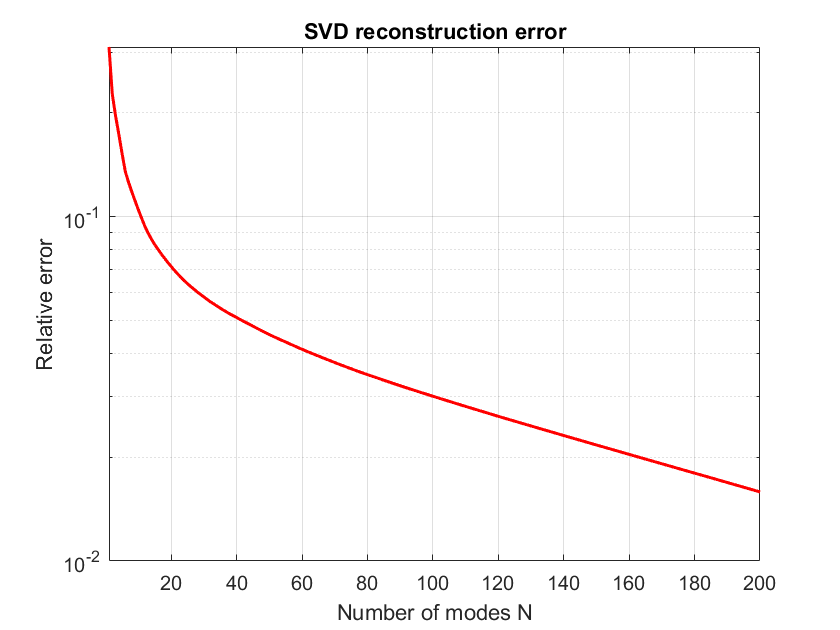

sigmas = diag(S);
total_energy = sum(sigmas.^2);
M_err = zeros(length(sigmas), 1);
for N = 1:length(sigmas)
    M_err(N) = sqrt(sum(sigmas(N+1:end).^2) / total_energy);
end

figure
semilogy(1:length(sigmas), M_err, 'r-', 'LineWidth', 1.5)
xlabel('Number of modes N')
ylabel('Relative error')
title('SVD reconstruction error')
grid on
xlim([1 200])
saveas(gcf, 'svd_error.png')

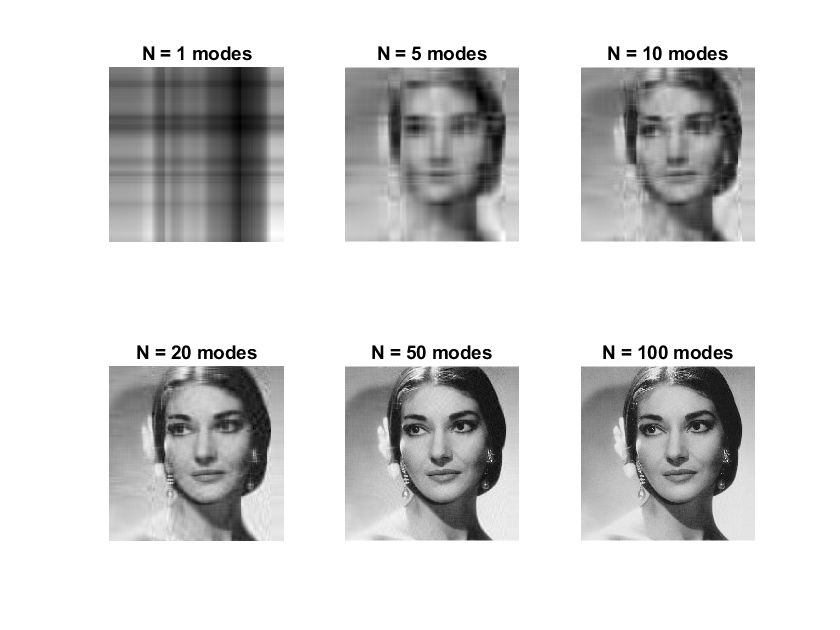

modes_show = [1, 5, 10, 20, 50, 100];
figure
for k = 1:6
    N = modes_show(k);
    M_approx = U(:,1:N) * S(1:N,1:N) * V(:,1:N)';
    subplot(2,3,k)
    colormap(gray); imagesc(M_approx); axis equal; axis tight; axis off;
    title(['N = ' num2str(N) ' modes'])
end
saveas(gcf, 'svd_reconstructions.png')

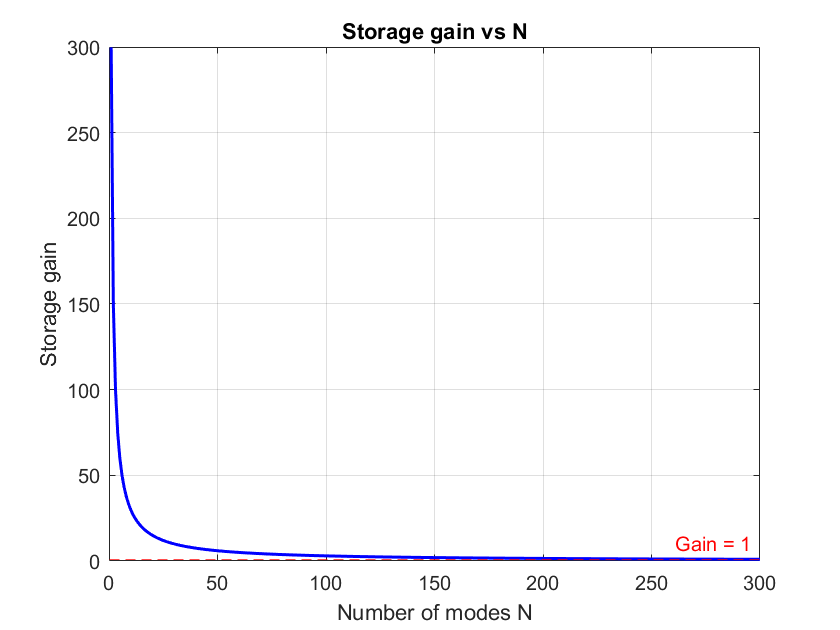

Ns = 1:300;
gains = (n_T * n_M) ./ (Ns * (n_T + n_M + 1));
figure
plot(Ns, gains, 'b-', 'LineWidth', 1.5)
hold on
yline(1, 'r--', 'Gain = 1')
xlabel('Number of modes N')
ylabel('Storage gain')
title('Storage gain vs N')
grid on
saveas(gcf, 'svd_gain.png')